## 载入神经网络

clear;clc;close all; fclose all;addpath("lib");
load 202002222009_epo3_itr6000.mat
%load Label.mat

## 载入音频输入

[snd,Fs] = audioread("录音 (4).m4a");
snd=resample(snd(:,1),16000,Fs);

% N=2;
% name = Label.filename{N};
% name= strrep(name,"D:\","..\变声器训练集\");
% name= strrep(name,"txt","wav");
%                 
% snd = audioread(name);
% textin = Label.text{N};
% clear ans name

## 送入神经网络

spect = toLogSpect(snd);
NNInput = dlarray(zeros(128,2560,'single'),"SSCB");  
NNInput(:,1:size(spect,2)) = spect;
ValidNNOutputsCount = ceil(1+(size(spect,2)-128)/32);

NNOutput = NN.forward(NNInput);
NNOutput(:,:,1:2  ,:) = softmax(NNOutput(:,:,1:2  ,:));
NNOutput(:,:,3:26 ,:) = softmax(NNOutput(:,:,3:26 ,:));
NNOutput(:,:,27:61,:) = softmax(NNOutput(:,:,27:61,:));
NNOutput(:,:,62:66,:) = softmax(NNOutput(:,:,62:66,:));
epsilon=1e-5;
NNOutput(NNOutput < epsilon)=NNOutput(NNOutput < epsilon)+epsilon;
NNOutput=-log(NNOutput);
NNOutput=squeeze(extractdata(NNOutput(:,1:ValidNNOutputsCount,:)));

clear epsilon NNInput spect ValidNNOutputsCount sound

## 简单贪心搜索

TODO beam搜索

    语音中前后俩字拼音一样的概率非常小，这里换beam搜索估计改善也不大

    后面拼音转文本（本程序没做）的时候根据词典进行最大似然匹配会有较大改善

TODO 利用声母韵母的配对关系排除一些异常匹配(如拼音bü pü 显然不存在)

% 判决
[~,Shuchu] = min(NNOutput(:,1:2),[],2);Shuchu=Shuchu==1;
[~,Shengmu] = min(NNOutput(:,3:26),[],2);
[~,Yunmu] = min(NNOutput(:,27:61),[],2);
[~,YinDiao] = min(NNOutput(:,62:66),[],2);
% 去除重复
Chongfu = [false;
Shuchu(2:end) == Shuchu(1:end-1) & ...
Shengmu(2:end) == Shengmu(1:end-1)& ...
Yunmu(2:end) == Yunmu(1:end-1)& ...
YinDiao(2:end) == YinDiao(1:end-1)];
Shuchu=Shuchu(~Chongfu);
Shengmu=Shengmu(~Chongfu);
Yunmu=Yunmu(~Chongfu);
YinDiao=YinDiao(~Chongfu);
% 去除空白
Shengmu=Shengmu(Shuchu);
Yunmu=Yunmu(Shuchu);
YinDiao=YinDiao(Shuchu);

## 查表转换成拼音

ShengmuBiao=["","b","p","m","f","d","t","n","l","g","k","h","w","j","q",...
    "x","y","r","z","c","s","zh","ch","sh"]';
YunmuBiao=["i","u","v","a","ia","ua","o","uo","e","ie","ve","ai",...
    "uai","ei","uei","ao","iao","ou","iou","an","ian","uan",...
    "van","en","in","uen","vn","ang","iang","uang","eng",...
    "ing","ueng","ong","iong"]';% v==ü
Shengmu=ShengmuBiao(Shengmu);
Yunmu=YunmuBiao(Yunmu);
PinYin = Shengmu+Yunmu+YinDiao;
% 拼音的后处理
Replace = [...
    "yu","ju","qu","xu","iu","ui","un";...
    "yv","jv","qv","xv","iou","uei","uen"];
for i=1:size(Replace,2)
    strrep(PinYin,Replace(2,i),Replace(1,i));% 处理一些拼音略写的情况
end
PinYin = strjoin(PinYin,"/");
clear ans i N Replace Shengmu  
clear YinDiao Yunmu 
%clear YunmuBiao ShengmuBiao


disp(PinYin);

mei2/yong3/gong4/chuan3/gang3/jiou4/mei2/you3/xin1/zhong1/guo2


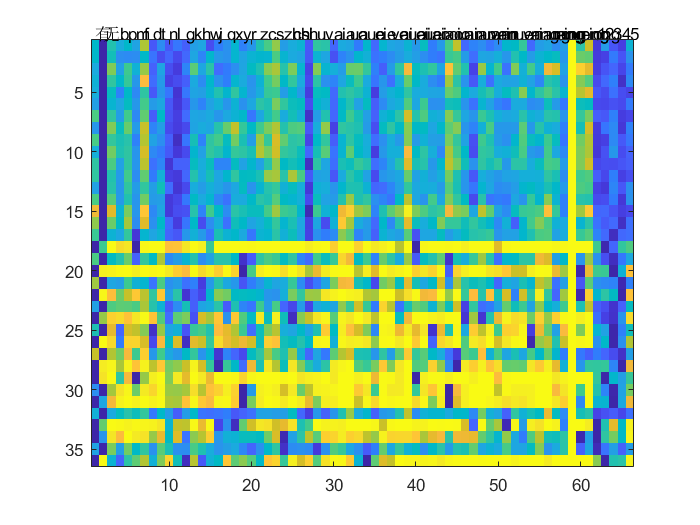

% disp(textin)
figure;
temp = NNOutput(~Chongfu,:);
Y=imagesc(NNOutput);
text(1:66,0*(1:66),["有";"无";ShengmuBiao;YunmuBiao;"1";"2";"3";"4";"5"]);
